%calculating the mean first passage time using Gillespie simulations
%to investigate effect of invader toehold length on RNA/DNA TMSD kinetics

b = 20 %define the branch migration domain length

b = 20

%g = 2 %define the invader toehold length

R = 1.987/1000 % universal gas constant in kcal/K/mol

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%define the free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGrd = -1*R*temp

dGrd = -0.5924

dGbm = 7.4*R*temp 

dGbm = 4.3839

%define the absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

N = 10 %number of simulations

N = 10

avr_first_pass_time = zeros(1,15)

avr_first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_first_pass_time = zeros(15, N)

ind_first_pass_time =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


k_eff = zeros(1, 15)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_k_eff = zeros(15, N)

ind_k_eff =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


std_err_fpt = zeros(1, 15)

std_err_fpt =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_k_eff = zeros(1, 15)

std_err_k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_log_k = zeros(1,15)

std_err_log_k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through the invader toehold lengths
for g = 1:15

    %define the forward and reverse rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-(dGbm - dGrd)/(R*temp))
    k_CD = k_bp * exp(-dGbm/(R*temp));
    k_DC = 0 
    k_DD = 1
    
    first_pass_time = zeros(1,N)
    
    %create arrays for forward and reverse rates
    if g == 1
        Kf = [k_AB1, k_C1f, repmat(k_Cf, [1, b-2]), k_CD, k_DD]
        Kb = [k_AA, k_B1A, k_Cr, repmat(k_Cr, [1 b-2]), k_DC]
    else
        Kf = [k_AB1, k_BC1ij, repmat(k_BC1ij, [1, g-2]), k_C1f, repmat(k_Cf, [1, b-2]), k_CD, k_DD]
        Kb = [k_AA, k_B1A, repmat(k_BC1ji, [1, g-2]), k_BC1ji, k_Cr, repmat(k_Cr, [1, b-2]), k_DC]
    end
    
    totalrate = Kf + Kb; %define the total rate
    Pf = Kf./totalrate; %define the probability of forward transition
    Pb = 1-Pf; %define the probability of backward transition
    %loop through the simulations
    for n = 1:N 
        state = 1; %define the initial state
        t = 0; %define the initial time
        %restrict the states which can be reached
        while (state >=1 && state < (2 + g + b)) 
            t = t - (1/totalrate(state))*log(rand()); %calculate time for transition
            %calculate whether forward or reverse transition
            if rand() <= Pf(state) 
                state = state +1; %update state forward
            else
                state = state -1; %update state backward
            end
        end
        first_pass_time(n) =  t; 
        ind_first_pass_time(g,n) = first_pass_time(n);
        ind_k_eff(g,n) = 1/(first_pass_time(n)*(5*10^-8));
    end
    std_err_fpt(g) = std(ind_first_pass_time(g, :))/sqrt(N); %calculate standard error
    std_err_k_eff(g) = std(ind_k_eff(g, :))/sqrt(N);
    std_err_log_k(g) = std(log10(ind_k_eff(g,:))/sqrt(N));
    avr_first_pass_time(g) = mean(first_pass_time)%calculate average first passage time
    k_eff(g) = 1/(mean(first_pass_time)*(5*10^-8))%calculate the effective rate constant
end

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time = 	1.0e+04 *

    1.2247         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    1.6331         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time = 	1.0e+04 *

    1.2247    0.0481         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+04 *

    0.1633    4.1571         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time = 	1.0e+04 *

    1.2247    0.0481    0.0014         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    0.0016    0.0416    1.4291         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time = 	1.0e+04 *

    1.2247    0.0481    0.0014    0.0009         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    0.0016    0.0416    1.4291    2.3489         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time = 	1.0e+04 *

    1.2247    0.0481    0.0014    0.0009    0.0008         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    0.0016    0.0416    1.4291    2.3489    2.6071         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time = 	1.0e+04 *

    1.2247    0.0481    0.0014    0.0009    0.0008    0.0005         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    0.0016    0.0416    1.4291    2.3489    2.6071    3.9989         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time = 	1.0e+04 *

    1.2247    0.0481    0.0014    0.0009    0.0008    0.0005    0.0006         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    0.0016    0.0416    1.4291    2.3489    2.6071    3.9989    3.1390         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time = 	1.0e+04 *

    1.2247    0.0481    0.0014    0.0009    0.0008    0.0005    0.0006    0.0004         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    0.0016    0.0416    1.4291    2.3489    2.6071    3.9989    3.1390    5.4196         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time = 	1.0e+04 *

    1.2247    0.0481    0.0014    0.0009    0.0008    0.0005    0.0006    0.0004    0.0008         0         0         0         0         0         0


k_eff =     0.0016    0.0416    1.4291    2.3489    2.6071    3.9989    3.1390    5.4196    2.6287         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000


Kb =          0    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =     1.2247    0.0481    0.0014    0.0009    0.0008    0.0005    0.0006    0.0004    0.0008    0.0005         0         0         0         0         0


k_eff =     0.0016    0.0416    1.4291    2.3489    2.6071    3.9989    3.1390    5.4196    2.6287    3.8433         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =     1.2247    0.0481    0.0014    0.0009    0.0008    0.0005    0.0006    0.0004    0.0008    0.0005    0.0006         0         0         0         0


k_eff =     0.0016    0.0416    1.4291    2.3489    2.6071    3.9989    3.1390    5.4196    2.6287    3.8433    3.3954         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =     1.2247    0.0481    0.0014    0.0009    0.0008    0.0005    0.0006    0.0004    0.0008    0.0005    0.0006    0.0006         0         0         0


k_eff =     0.0016    0.0416    1.4291    2.3489    2.6071    3.9989    3.1390    5.4196    2.6287    3.8433    3.3954    3.3253         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =     1.2247    0.0481    0.0014    0.0009    0.0008    0.0005    0.0006    0.0004    0.0008    0.0005    0.0006    0.0006    0.0004         0         0


k_eff =     0.0016    0.0416    1.4291    2.3489    2.6071    3.9989    3.1390    5.4196    2.6287    3.8433    3.3954    3.3253    4.7928         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =     1.2247    0.0481    0.0014    0.0009    0.0008    0.0005    0.0006    0.0004    0.0008    0.0005    0.0006    0.0006    0.0004    0.0006         0


k_eff =     0.0016    0.0416    1.4291    2.3489    2.6071    3.9989    3.1390    5.4196    2.6287    3.8433    3.3954    3.3253    4.7928    3.4284         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =     1.2247    0.0481    0.0014    0.0009    0.0008    0.0005    0.0006    0.0004    0.0008    0.0005    0.0006    0.0006    0.0004    0.0006    0.0011


k_eff =     0.0016    0.0416    1.4291    2.3489    2.6071    3.9989    3.1390    5.4196    2.6287    3.8433    3.3954    3.3253    4.7928    3.4284    1.7400


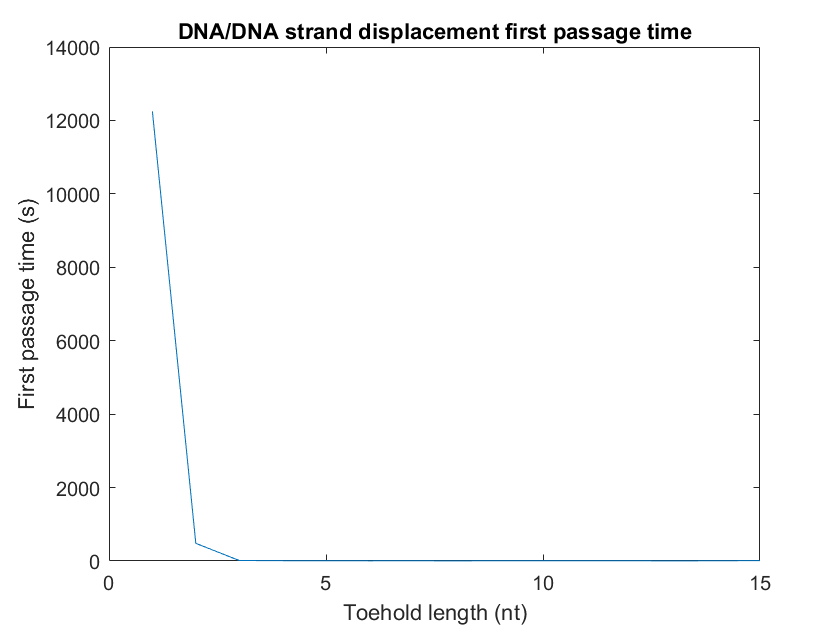

plot(1:15, avr_first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

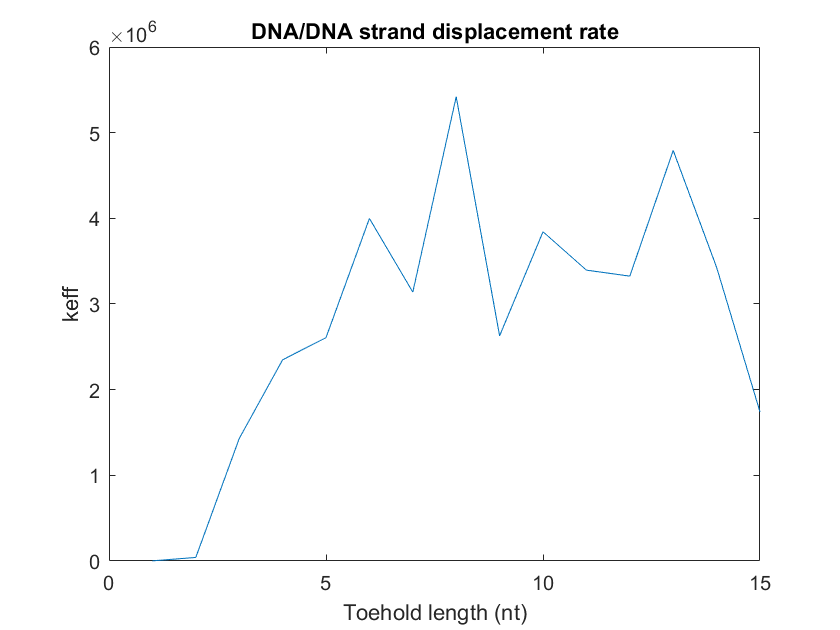


plot(1:15, k_eff)
ylabel('keff')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

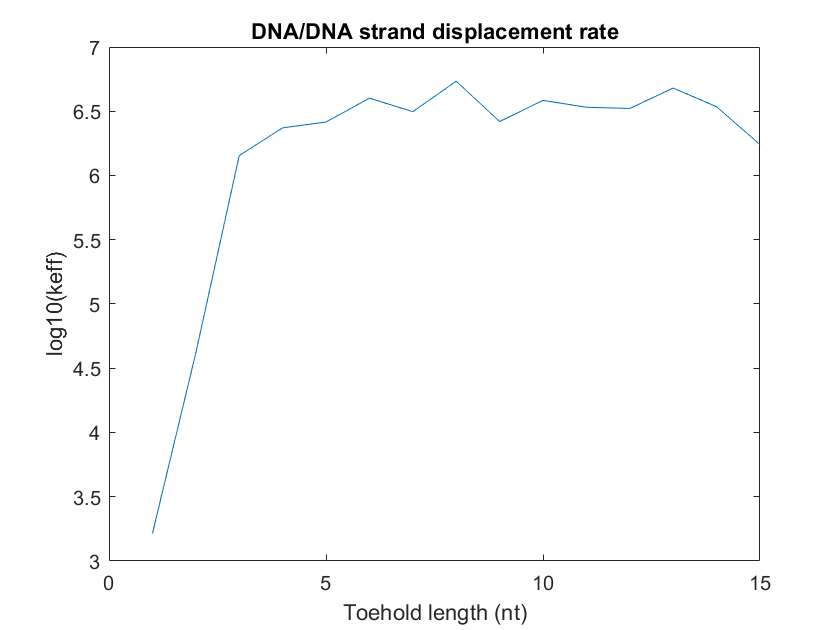


plot(1:15, log10(k_eff))
ylabel('log10(keff)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

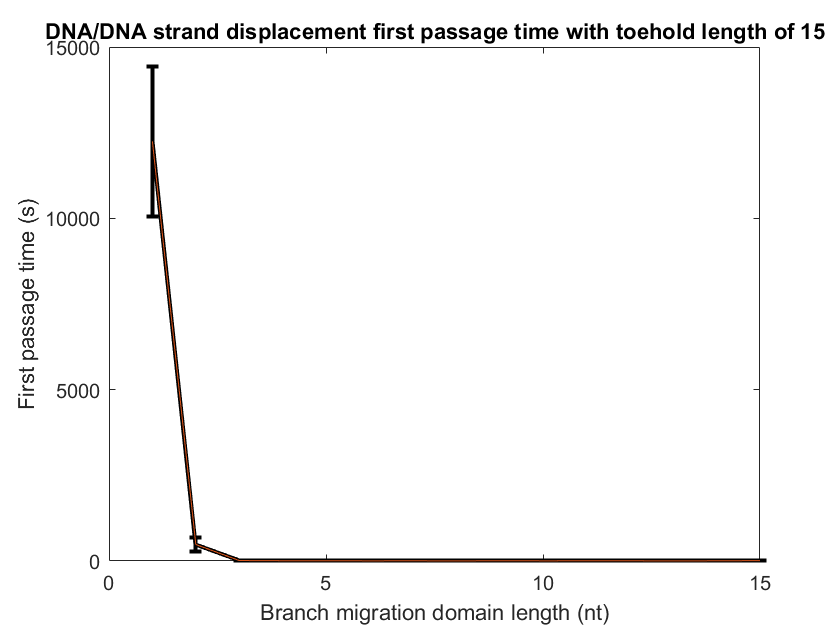


errorbar(1:15, avr_first_pass_time, std_err_fpt , 'k', 'linewidth', 2)
hold on
plot(1:15, avr_first_pass_time, 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('First passage time (s)')
title('DNA/DNA strand displacement first passage time with toehold length of ' + string(g))

hold off

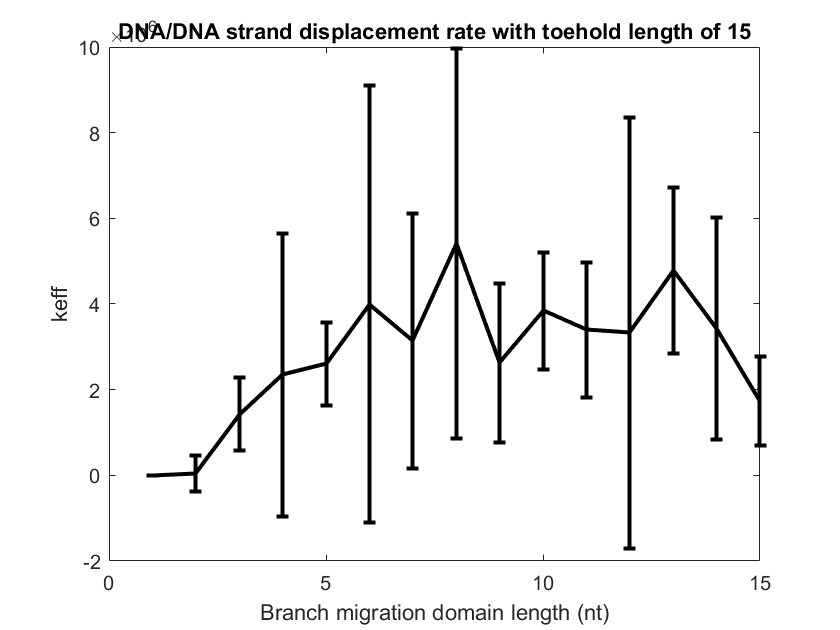


errorbar(1:15, k_eff, std_err_k_eff, 'k', 'linewidth', 2)
xlabel('Branch migration domain length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off

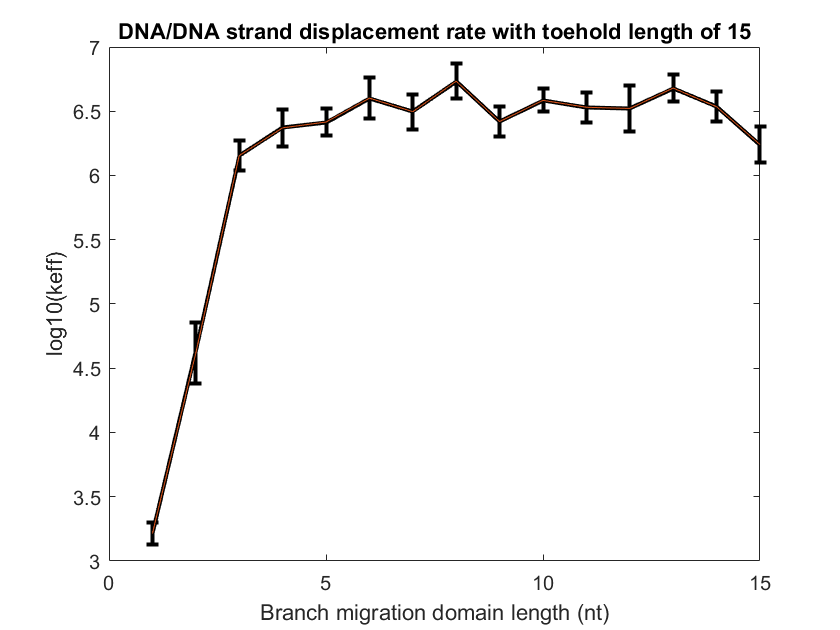


errorbar(1:15, log10(k_eff), std_err_log_k, 'k', 'linewidth', 2)
hold on
plot(1:15, log10(k_eff), '', 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off